%test %audio filename must in same directory of this m file
Filename = 'piano_middle_C.wav';
% First read wav file into memory
[Sig, Fs]=audioread(Filename);
%Sig stores raw audio data in column;
%Fs sampling frequency
audioinfo(Filename)

ans = struct with fields:
             Filename: '/Users/lewisemery/DIG5111-New-/piano_middle_C.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 44100
         TotalSamples: 331776
             Duration: 7.5233
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


Duration = length(Sig)/Fs;
disp(Duration);

    7.5233



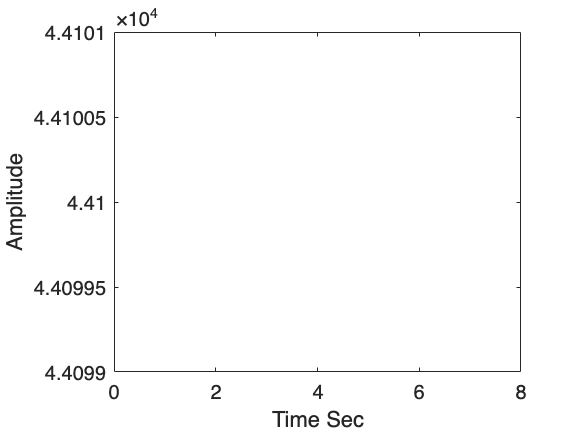

Ts = 1/Fs;
Time = 0:Ts:Duration;
plot(Ts, Fs, Duration, Fs);
ylabel('Amplitude');
xlabel('Time Sec');